# Calibration

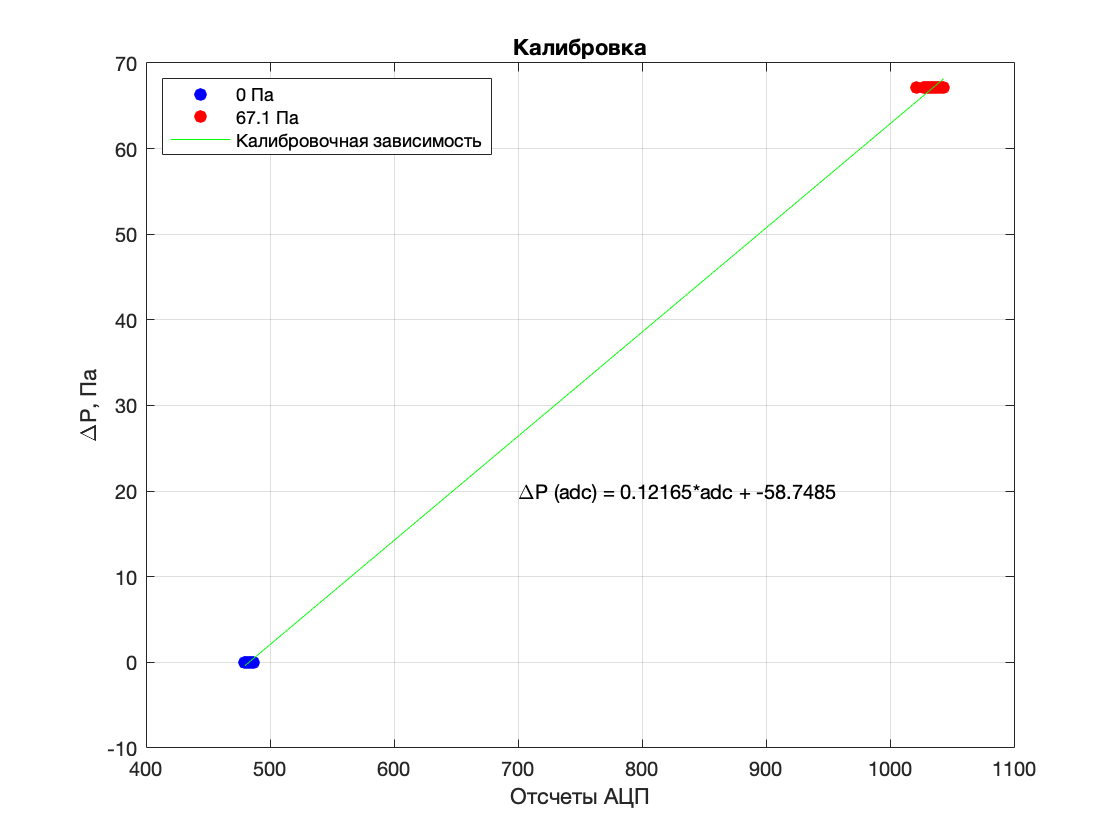

calibzero0 = load('/Users/karimvafin/Downloads/jet/2-experimentData/calibzero.dat');
calib0 = load('/Users/karimvafin/Downloads/jet/2-experimentData/calib.dat');

calibzero = (calibzero0(:,2))';
calib = (calib0(:,2))';

x = [calibzero calib];

manometer = ones(size(calib)).*67.1;
null = zeros(size(calibzero));

y = [null manometer];

p = polyfit(x, y, 1);

f1 = figure;
figure(f1);
plot(calibzero, null, 'bo', 'MarkerFaceColor','b');
hold on;
grid on;
plot(calib, manometer, 'ro', 'MarkerFaceColor','r');

x1 = [min(calibzero) max(calib)];
y1 = [polyval(p, x1(1)) polyval(p, x1(2))];

plot(x1, y1, 'Color', 'g');

title('Калибровка');
xlabel('Отсчеты АЦП');
ylabel('\DeltaP, Па');

str = ['\DeltaP (adc) = ' num2str(p(1)) '*adc + ' num2str(p(2))];
text(700, 20, str);

legend('0 Па', '67.1 Па', 'Калибровочная зависимость', 'Location','northwest');

saveas(f1, 'calibration(jet).png')

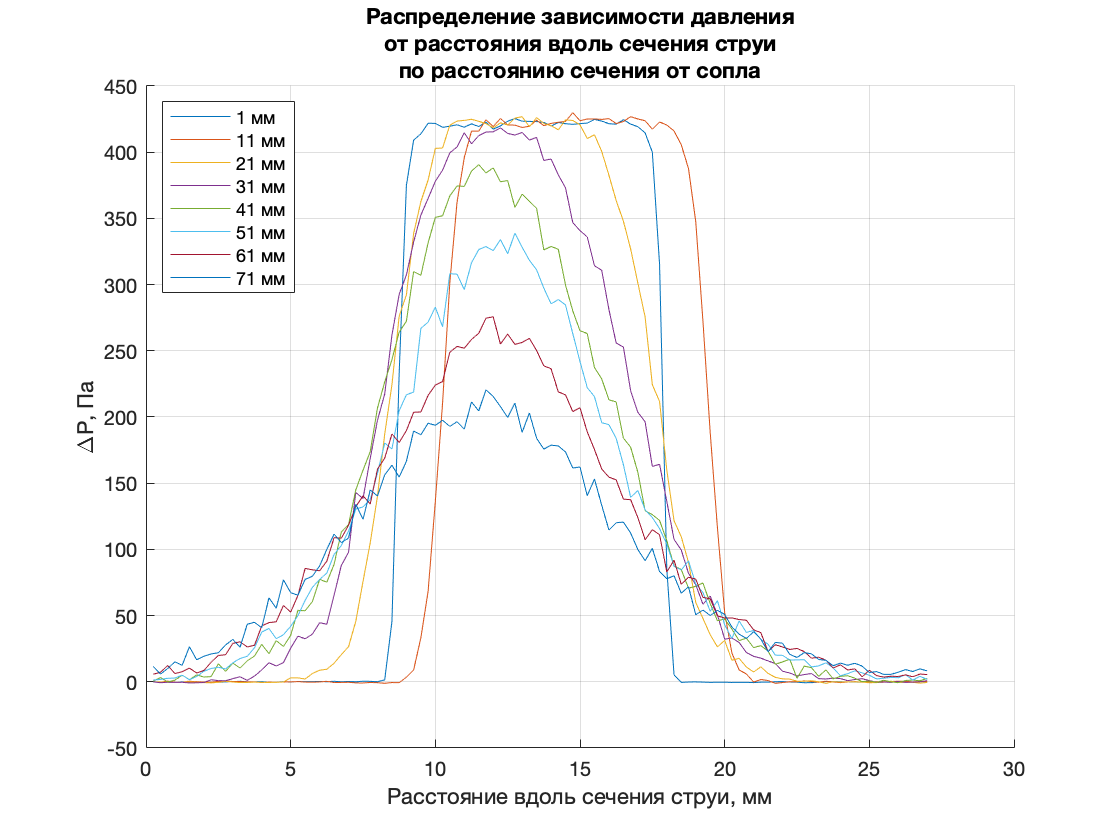

%%Loading data
mm01 = load('/Users/karimvafin/Downloads/jet/2-experimentData/01mm.dat');
mm11 = load('/Users/karimvafin/Downloads/jet/2-experimentData/11mm.dat');
mm21 = load('/Users/karimvafin/Downloads/jet/2-experimentData/21mm.dat');
mm31 = load('/Users/karimvafin/Downloads/jet/2-experimentData/31mm.dat');
mm41 = load('/Users/karimvafin/Downloads/jet/2-experimentData/41mm.dat');
mm51 = load('/Users/karimvafin/Downloads/jet/2-experimentData/51mm.dat');
mm61 = load('/Users/karimvafin/Downloads/jet/2-experimentData/61mm.dat');
mm71 = load('/Users/karimvafin/Downloads/jet/2-experimentData/71mm.dat');

dx = 0.25;
x = mm01(:,1)'.*dx;

p01 = polyval(p, mm01(:, 2)');
p11 = polyval(p, mm11(:, 2)');
p21 = polyval(p, mm21(:, 2)');
p31 = polyval(p, mm31(:, 2)');
p41 = polyval(p, mm41(:, 2)');
p51 = polyval(p, mm51(:, 2)');
p61 = polyval(p, mm61(:, 2)');
p71 = polyval(p, mm71(:, 2)');

pressure = [p01; p11; p21; p31; p41; p51; p61; p71];
Names = {'1 мм', '11 мм', '21 мм', '31 мм', '41 мм', '51 мм', '61 мм', '71 мм'};

f2 = figure;
figure(f2);
hold on;
grid on;
title({'Распределение зависимости давления', 'от расстояния вдоль сечения струи', 'по расстоянию сечения от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 1)
    plot(x, pressure(i,:),'DisplayName', Names{i});
end

legend('Location',"northwest");

saveas(f2, 'pressure(jet).png');

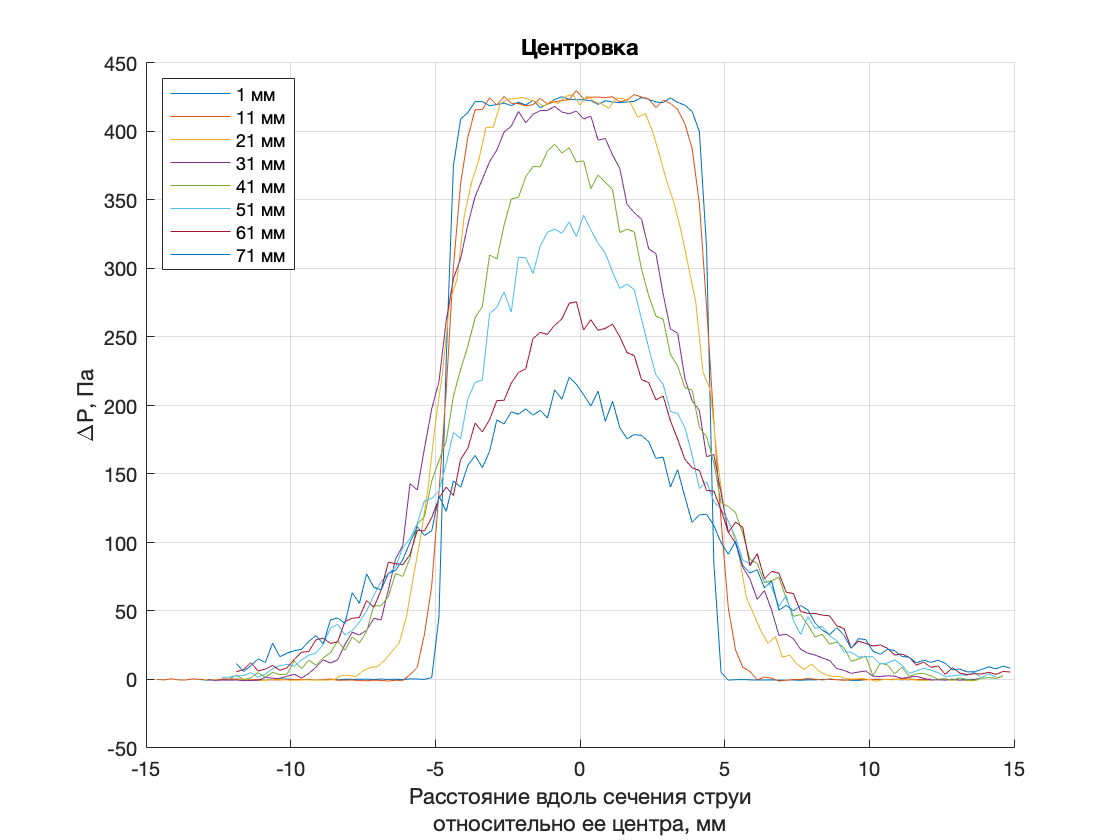

%%Shift

f3 = figure;
figure(f3);
hold on;
grid on;
title('Центровка');
ylabel('\DeltaP, Па');
xlabel({'Расстояние вдоль сечения струи','относительно ее центра, мм'});

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure,1)
    max = x(find(pressure(i,:) > offset, 1, "last"));
    min = x(find(pressure(i,:) > offset, 1, 'first'));
    center = min + (max - min)/2;
    xCentered(i,:) = x - center;
    plot(xCentered(i,:), pressure(i,:), 'DisplayName', Names{i});
end

legend('Location',"northwest");

saveas(f3, 'centeredpressure(jet).png');

%%Calculating the speed
ro = 1.2;
sum = 0;
for i = 1:length(calibzero)
    sum = sum + calibzero(i);
end
sum = sum/length(calibzero);
Pst = polyval(p, sum);
P0 = polyval(p, calib);

v01 = sqrt(2*abs(p01 - Pst)/ro);
v11 = sqrt(2*abs(p11 - Pst)/ro);
v21 = sqrt(2*abs(p21 - Pst)/ro);
v31 = sqrt(2*abs(p31 - Pst)/ro);
v41 = sqrt(2*abs(p41 - Pst)/ro);
v51 = sqrt(2*abs(p51 - Pst)/ro);
v61 = sqrt(2*abs(p61 - Pst)/ro);
v71 = sqrt(2*abs(p71 - Pst)/ro);

v = [v01; v11; v21; v31; v41; v51; v61; v71];

xvCentered = zeros(size(v));
offset = 12;

hold off;

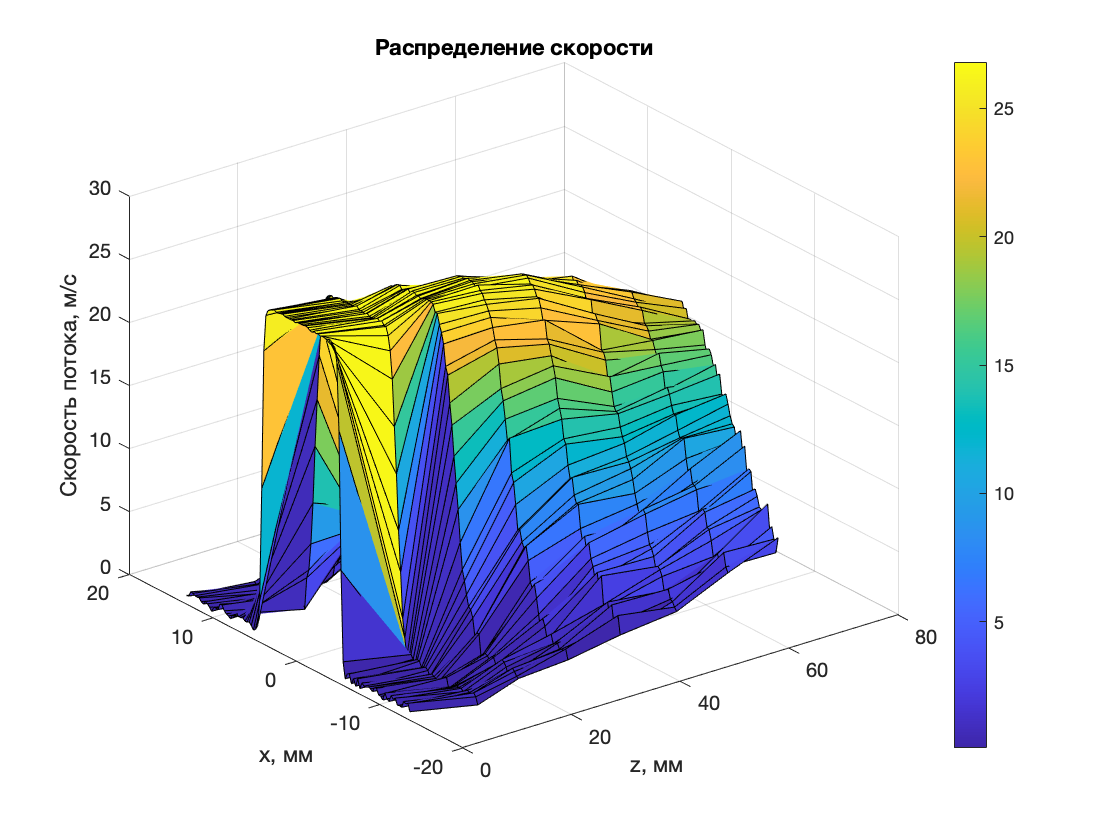


for i = 1:size(v,1)
    max = x(find(v(i,:) > offset, 1, "last"));
    min = x(find(v(i,:) > offset, 1, 'first'));
    center = min + (max - min)/2;
    xvCentered(i,:) = x - center;
end

f4 = figure;
figure(f4);

plot3(10,10,10);

hold on;
grid on;

z = ones(size(pressure));

for i = 1:8
    z(i,:) = z(i,:)*((i - 1)*10 + 1);
end

surf(z, xvCentered, v);
title('Распределение скорости');
colorbar;

xlabel('z, мм');
zlabel('Скорость потока, м/с');
ylabel('x, мм');

saveas(f4, 'v(jet).png');

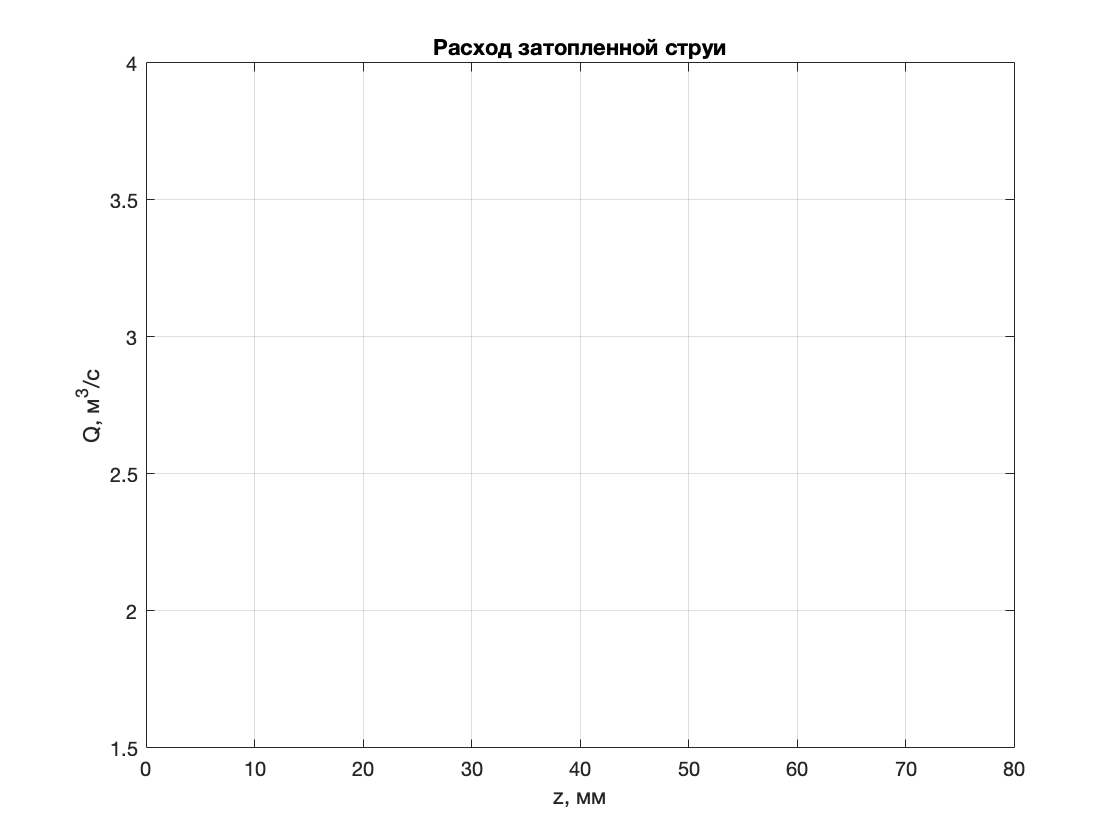

%%Calculating flowrate

Q = zeros(8);

for i = 1:size(v,1)
    y0 = v(i,:).*abs(xvCentered(i,:));
    x0 = xvCentered(i,:).*10^(-3);
    Q(i) = 2*1.2*pi*trapz(x0,y0);
end

Q = Q(:,1)'/2; % так как интеграл брался от -r до r

hold off;

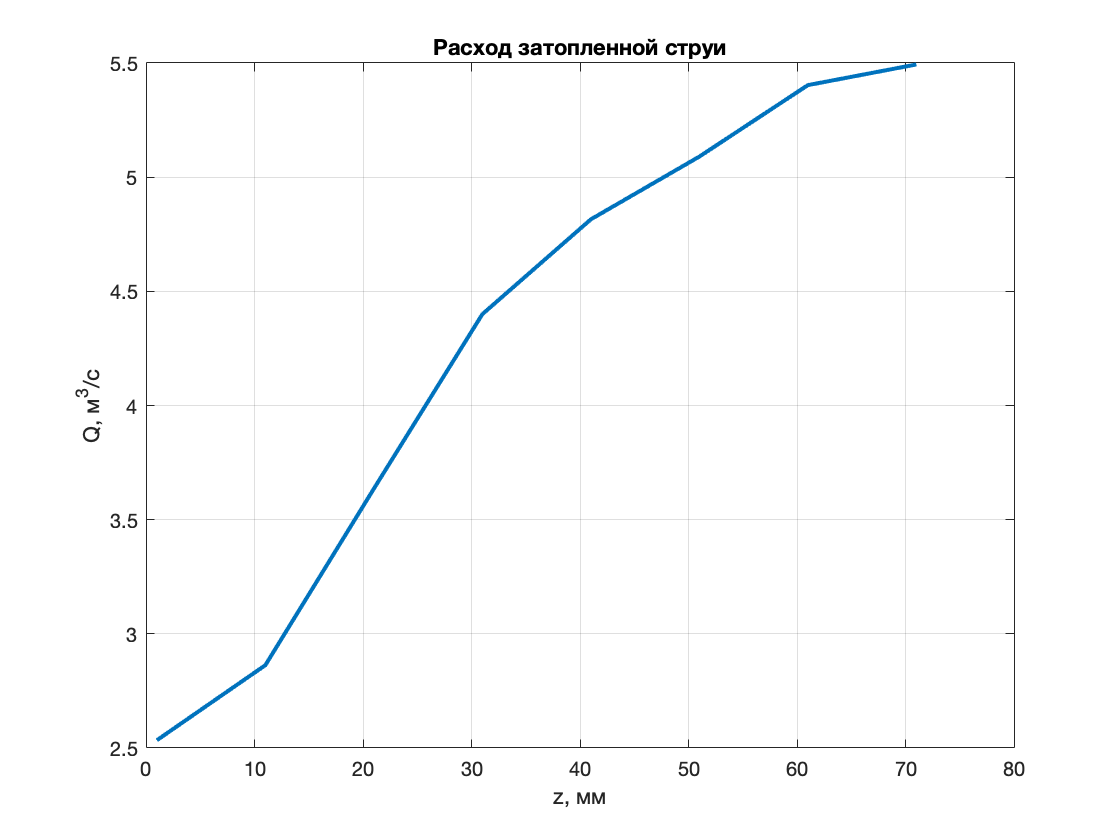


f5 = figure;
figure(f5);
plot(z(:,1)', Q, 'LineWidth',2);
grid on;
title('Расход затопленной струи');
ylabel('Q, м^3/c');
xlabel('z, мм');

saveas(f5, 'flowrate(jet).png');